Parameters   [oooooooooooooooooooooooooooooooooooooooooooooooooo]     1 seconds
Channels     [oooooooooooooooooooooooooooooooooooooooooooooooooo]   157 seconds
Merging      [oooooooooooooooooooooooooooooooooooooooooooooooooo]     2 seconds
Spliting channels between sectors...Time taken for simulation = 161.0 s

Elapsed time is 80.251639 seconds.


Total time = 82.9 s

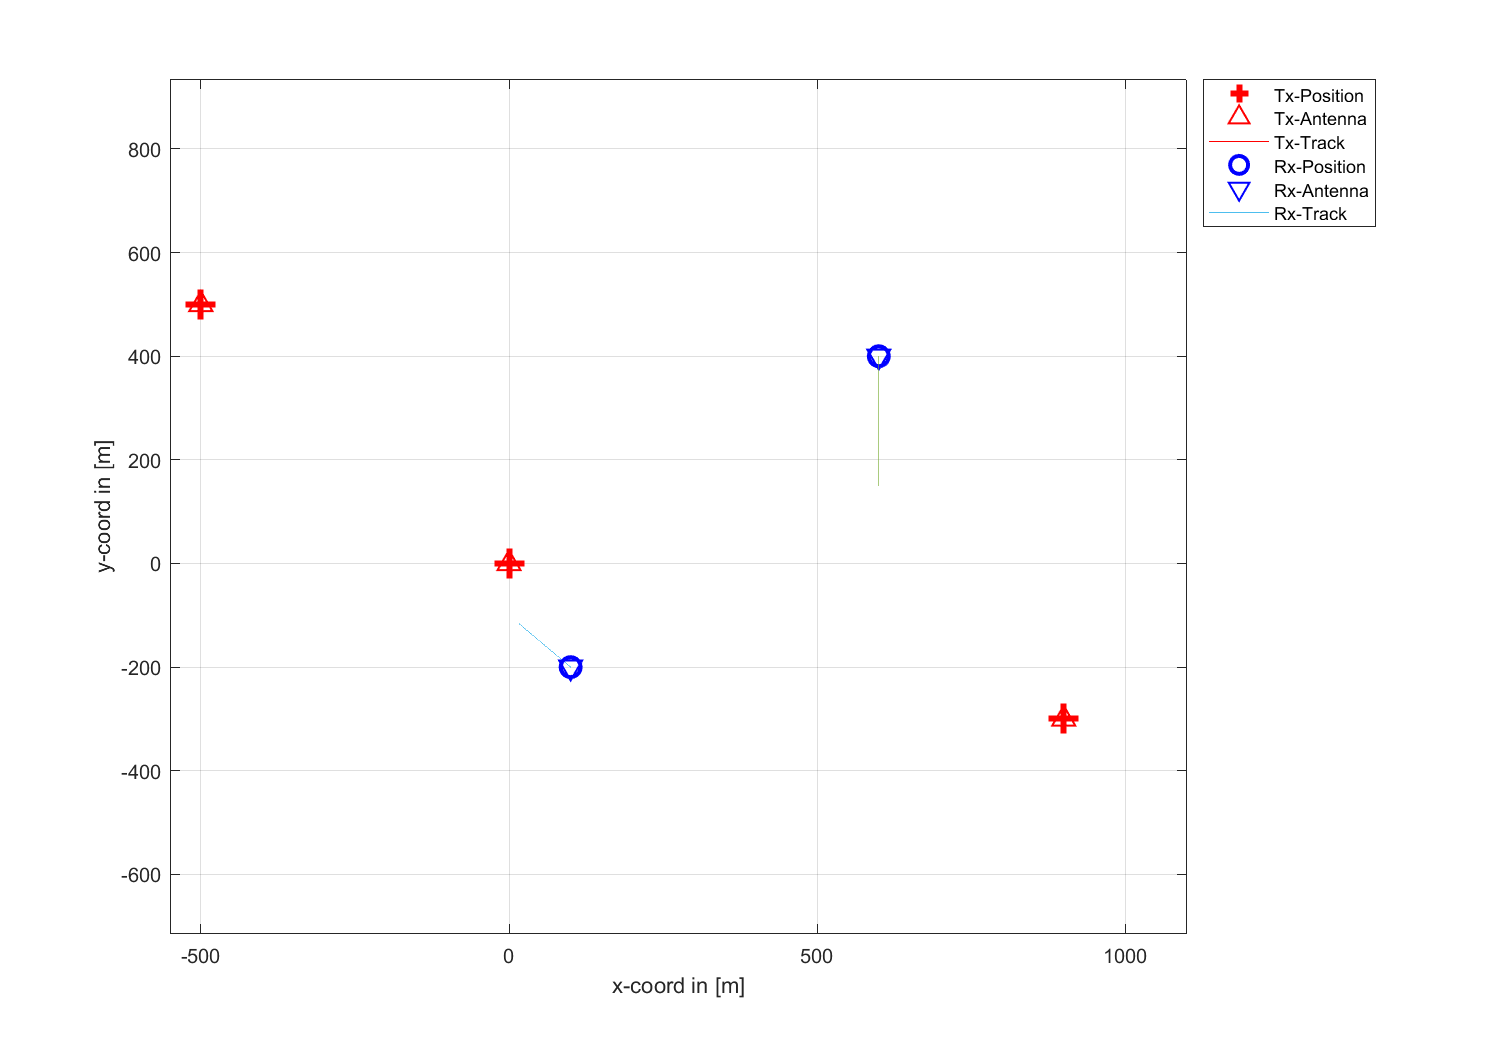

SimpleUE;

## Wideband RSRP


useful_fft_points = 600;

pg_eff = zeros(l.no_rx, l.no_tx*N_SECTORS(1)); % Calculate the effective path gain from the channels

mimo_no_tx = l.tx_array(1, 1).no_elements / N_SECTORS(1);
mimo_no_rx = l.rx_array(1, 1).no_elements;
no_mimo_links = mimo_no_tx * mimo_no_rx; % Get the number of MIMO sub-channels in the channel matrix

for ir = 1:l.no_rx % Extract effective PG vor each BS-MT link
    for it = 1:l.no_tx * N_SECTORS(1)
        pg_eff(ir, it) = sum(abs(c(ir, it).coeff(:)).^2) / no_mimo_links;
    end
end

% Calculate the coupling loss from the effective PG
coupling_loss = 10 * log10(max(pg_eff(:, :), [], 2));

% Wideband SINR
% The wideband SINR is essentially the same as the GF. However, the 3GPP model uses the RSRP values
% for the calculation of this metric. The calculation method is described in 3GPP TR 36.873 V12.5.0
% in Section 8.1 on Page 38. Essentially, the RSRP values describe the average received power (over
% all antenna elements at the receiver) for each transmit antenna port. Hence, in the phase 2
% calibration, there are 4 RSRP values, one for each transmit antenna. The wideband SINR is the GF
% calculated from the first RSRP value, i.e. the average power for the first transmit antenna port.

% Assume equal power in each sector tx
pwr_mW_perSC_perMIMOtx = (10^(0.1 * Tx_P_dBm(1, 1)) / useful_fft_points / mimo_no_tx);
sector_pwr = pwr_mW_perSC_perMIMOtx * ones(l.no_tx*N_SECTORS(1), 1);

rsrp_p0 = zeros(l.no_rx, l.no_tx*N_SECTORS(1), total_time*fs);

% Calculate the RSRP value from the first transmit antenna:
for ir = 1:l.no_rx
    for it = 1:l.no_tx * N_SECTORS(1)
        for is = 1:total_time*fs
            tmp = c(ir, it).coeff(1, 1, :, is); % Coefficients from first Tx antenna
            rsrp_p0(ir, it, is) = 10*log10((sector_pwr(it)) * sum(abs(tmp(:)).^2) / l.rx_array(1, 1).no_elements); % Divide by num Rx antennas
        end
    end
end
rsrp_p0(:, :, 1) % each sectors results, time instance 1

ans =  -155.5006 -142.7477 -132.8362 -162.7534 -162.9053 -141.3585 -126.1626 -133.2166 -131.5037
 -156.2919 -153.1938 -133.7802 -138.0407 -155.8567 -145.4607 -149.4324 -151.2273 -151.2273


## PSD RSRP


BW = 10;

BW_options   = [1.25, 2.5, 5, 10, 15, 20]; % requested bandwidth should be one of these
FFT_Sampling = [1.92, 3.84, 7.68, 15.36, 23.04, 30.72]*10e6;
FFT_options  = [128, 256, 512, 1024, 1536, 2048, ];
RB_options   = [6, 12, 25, 50, 75, 100];
SC_options   = 12 * RB_options;


choice = find(BW_options == BW);
if isempty(choice)
    choice = find(BW_options*10e6 == BW);
    if isempty(choice)
        error("No valid BW selected, try again");
    end
else
    BW = 10e6*BW;
end

num_RBs = RB_options(choice);
fft_size = FFT_options(choice);
fft_freq = FFT_Sampling(choice);
RB_BW = 180e3;
subcarrier_spacing_Hz = 15e3;


Tx_P = 10.^(0.1 * Tx_P_dBm);

Y = zeros(l.no_rx, l.no_tx*N_SECTORS(1), total_time*fs);
for i_rx=1:l.no_rx
    for i_tx=1:l.no_tx*N_SECTORS(1)
        X = c(i_rx, i_tx).fr(BW, fft_size);
        X = squeeze(X);
        X = abs(X).^2./(fft_size) .* Tx_P(1, 1); % normalization
%         X = abs(X).^2 .* Tx_P(1, 1);
        Y(i_rx, i_tx, :) = 10*log10(mean(X, 1));
    end
end
Y(:, :, 1) % each sectors results, time instance 1

ans =  -156.8217 -148.0602 -134.8715 -166.4030 -166.7333 -144.8404 -128.5663 -135.5360 -133.7994
 -158.5192 -155.5021 -136.0923 -138.4858 -157.6575 -147.6373 -151.8213 -153.6836 -153.6836


## Difference

Z = Y - rsrp_p0;
Z(:, :, 1)

ans =    -1.3211   -5.3125   -2.0353   -3.6496   -3.8280   -3.4819   -2.4037   -2.3195   -2.2957
   -2.2273   -2.3083   -2.3121   -0.4452   -1.8008   -2.1766   -2.3889   -2.4562   -2.4563


mean_z = mean(Z, 'all')

mean_z = -2.3790